# Cilindro de raio 1 e altura 1 "escavado" por um cone com as mesmas dimensões

**Cilindro de raio 1 e altura 1:**

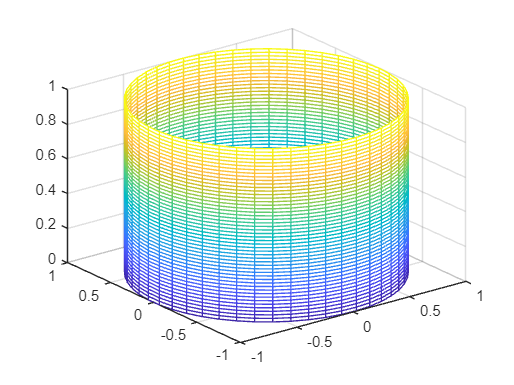

%passo 01: grelha de pontos das variaveis independentes

theta = linspace(0,2*pi,50);
z = linspace(0,1,50);

[theta,z] = meshgrid(theta,z);

%passo 02: declarar e definir a variavel dependente (rho)

rho = 1;

%passo 03: transformar as cords cilindricas em cartesianas

[xCilindro,yCilindro,zCilindro] = pol2cart(theta,rho,z);

%passo 04: esboçar a superficie
mesh(xCilindro,yCilindro,zCilindro)

**Chapa circular de raio 1 :**

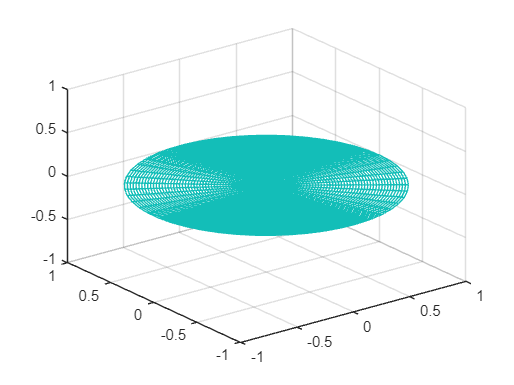

%passo 01: grelha de pontos das variaveis independentes

theta = linspace(0,2*pi,50);
rho = linspace(0,1,50);
z = linspace(0,1,50);

[theta,rho] = meshgrid(theta,rho);

%passo 02: declarar e definir a variavel dependente (rho)

z = zeros(50,50);

%passo 03: transformar as cords cilindricas em cartesianas

[xChapa,yChapa,zChapa] = pol2cart(theta,rho,z);

%passo 04: esboçar a superficie
mesh(xChapa,yChapa,zChapa)

**Cone de raio 1 e altura 1:**

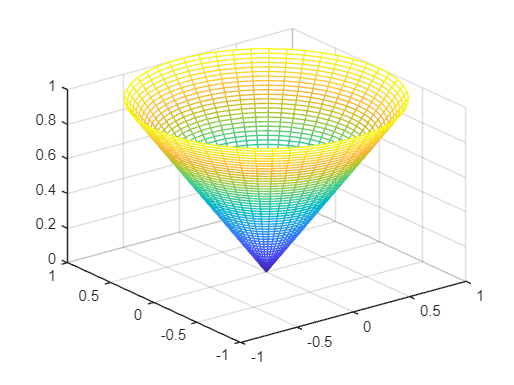

%passo 01: grelha de pontos das variaveis independentes

theta = linspace(0,2*pi,50);
rho = linspace(0,1,50);
z = linspace(0,1,50);

[theta,rho] = meshgrid(theta,rho);

%passo 02: declarar e definir a variavel dependente (rho)

z = rho;

%passo 03: transformar as cords cilindricas em cartesianas

[xCone,yCone,zCone] = pol2cart(theta,rho,z);

%passo 04: esboçar a superficie
mesh(xCone,yCone,zCone)

**Juntar as três peças:**

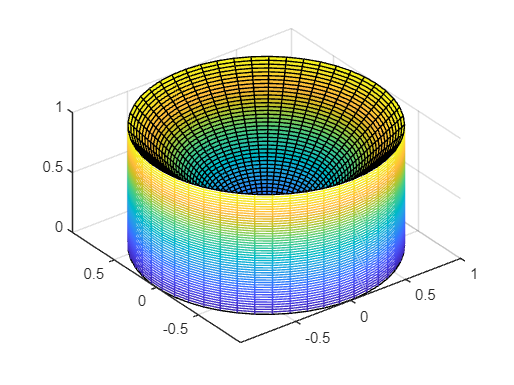

mesh(xCilindro,yCilindro,zCilindro)
hold on
surf(xCone,yCone,zCone)
surf(xChapa,yChapa,zChapa)
hold off
axis equal

**volume do solido:**

syms z rho theta

volume = int(int(int(rho,z,0,rho),theta,0,2*pi),rho,0,1)

$$volume = \frac{2\,\pi }{3}$$

var = vpa(volume)

$$var = 2.0943951023931954923084289221863$$